# Two Dimensional Brownian Motion

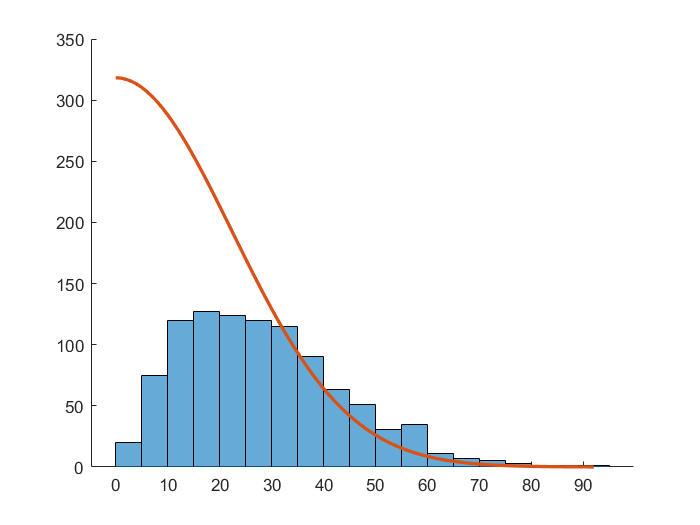

num_trials = 1000;
num_steps = 1000;
angle_values = 2*pi*rand(num_steps,num_trials);
dx_values = cos(angle_values);
dy_values = sin(angle_values);

distance_values = sqrt( power(sum(dx_values,1),2) + power(sum(dy_values,1),2) );
figure
hold on
histogram(abs(distance_values))
plot(0:max(distance_values),num_trials^2*exp(-power(0:max(distance_values),2)/num_steps)/pi/num_steps,'LineWidth',2)

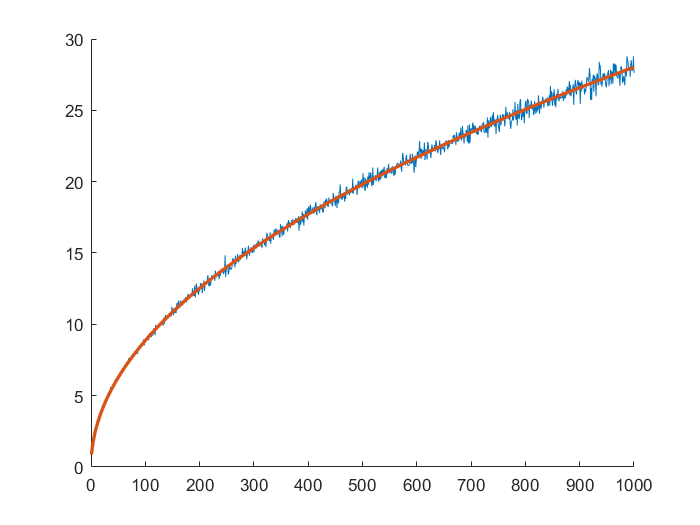


num_trials = 1000;
step_range = 1:1000;
average_dist = zeros(1,length(step_range));
for ii = step_range
    angle_values = 2*pi*rand(ii,num_trials);
    dx_values = cos(angle_values);
    dy_values = sin(angle_values);
    average_dist(ii) = mean( sqrt( power(sum(dx_values,1),2) + power(sum(dy_values,1),2) ) );
end
    
figure
hold on
plot(step_range,average_dist)
plot(step_range,sqrt(step_range)*sqrt(pi)/2,'LineWidth',2)